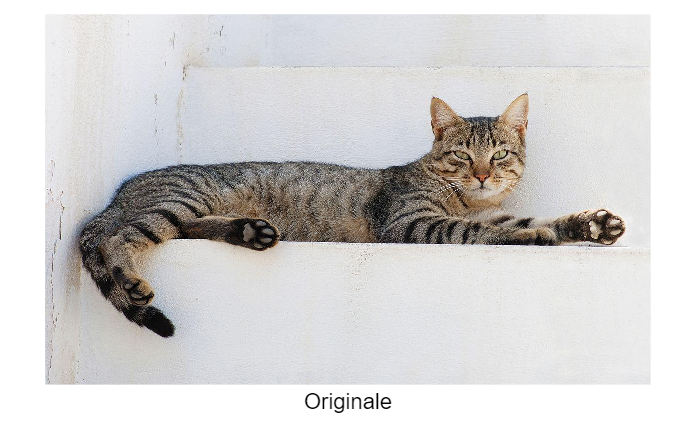

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);

i2 = imread(folderPath);
imshow(i2)
text(size(i2,2)/2, size(i2,1) + 10, 'Originale', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Applicazione Rumore Uniforme

Più "a" e "b" sono distanziate, più la varianza è alta. Più la varianza è alta, più il rumore è forte.

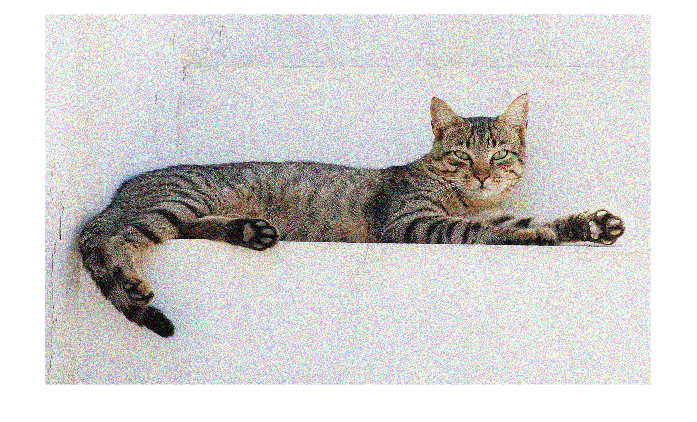

I = i2;  % deve essere uint8

a = -50;
b = 50;

% Crea rumore in double, tra -20 e 20
noise = (b - a) * rand(size(I)) + a;

% Somma immagine con rumore, convertendo in double per calcoli
noisy_img = double(I) + noise;

% Ritaglia i valori tra 0 e 255
noisy_img = uint8(min(max(noisy_img, 0), 255));

% Mostra immagine
imshow(noisy_img);

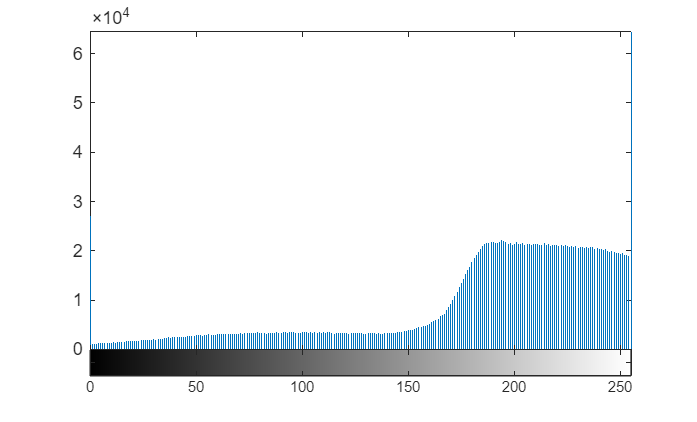

imhist(noisy_img);

L'istogramma mostra una variabile aleatoria uniforme.

Filtro di Weiner

Finestra 3x3 è meglio di 5x5

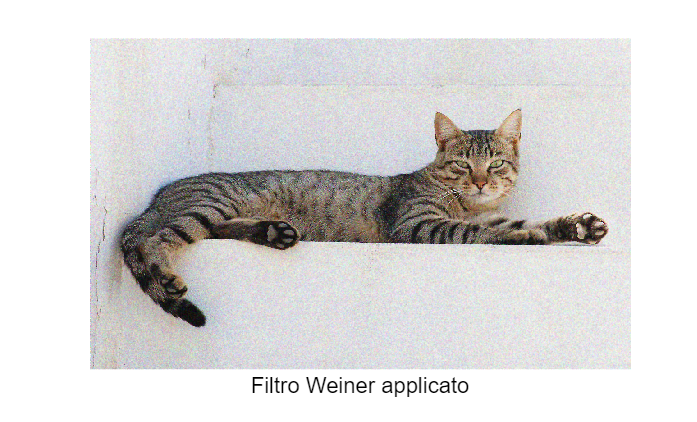

img_denoised = img_noisy;
for c = 1:3
    img_denoised(:,:,c) = wiener2(noisy_img(:,:,c), [3 3]);
end

imshow(img_denoised,[])
text(size(i2,2)/2, size(i2,1) + 10, 'Filtro Weiner applicato', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);